clear all; clc

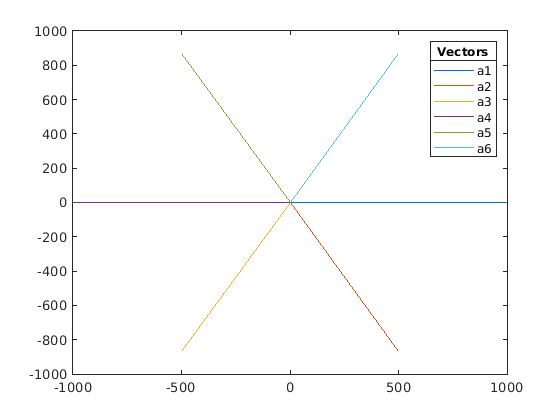

origin = [0,0];
a1 = [1000, 0]; % Basically [1,0] * 1000
a2 = [500, -866]; %[1/2, sqrt(3)/2] * 1000 ..so on
a3 = [-500, -866];
a4 = [-1000, 0];
a5 = [-500, 866];
a6 = [500, 866];

vectors =[a1;a2;a3;a4;a5;a6];
plot_vectors(vectors') % plots the vectors.


%{                 
                     N
                     |
Some more info   W-------E
                     |
                     S
First NN : E
Second NN : SE
Third NN : SW
Fourth NN : W
Fifth NN : NW
Sixth NN : NE

%}



nsite = 100; % Number of sites. 
%{ 
Total number of sites in visualization would be larger because it also 
shows the nearest neigbors of the lattice specified 
%}

nnb =6; % Number of nearest neighbors. 
site_index = 2;
nn_mat = zeros(nsite,nnb);
site_pos = zeros(1,2);
temp_site_pos = zeros(nnb,2);
for site = 1: nsite
    for nbd = 1: nnb
        origin = site_pos(site,:); % Setting site position as origin
        pos = origin + vectors(nbd,:); % Finding site position along the vectors
        val = ismember(pos,site_pos); % checking if the site position coincide with previous site positions 
        index = find_index(site_pos,pos);
        if all(val) ~= 1 || index == 0 % current position ~= any previous one and another case arises as well. see find_index().
            temp_site_pos(nbd , :) = pos;  % save the current pos in site_pos database
            nn_mat(site,nbd) = site_index; % Save the index of the site in matrix nn_mat
            site_index = site_index + 1;
        else % current pos matches with previous 
            nn_mat(site,nbd) = index; % instead of placing new value it uses the correct site position
        end           
    end
    temp_site_pos( all(~temp_site_pos,2), : ) = []; % Remove the rows which are zeros from temp_site_pos
    site_pos = vertcat(site_pos,temp_site_pos); % append the temp_site_pos to site_pos
    temp_site_pos = []; %Emptying the temp_site_pos matrix for next iteration. 
    % Necessary because we don't want to save the site_pos of positions
    % which are already present.
end

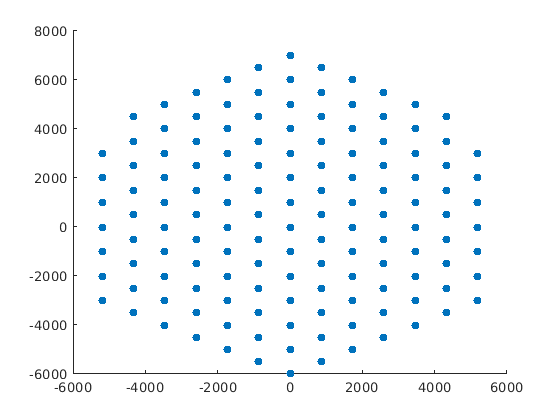

visualize(site_pos) % plots the lattice points

#### Function to plot the vectors.

function plot_vectors(vectors)
plotv(vectors,'-')
lgd = legend("a1","a2","a3","a4","a5","a6");
title(lgd,'Vectors')
end

#### Function to visualize the lattice.

function visualize(site_pos)
x = site_pos(:,1);
y = site_pos(:,2);
scatter(y,x,'o','filled')
end


#### Function to find index.

function index = find_index(site_pos, pos)
index1 = find(site_pos == pos(1,1)); % Looks for index of first entry in site_pos
index2 = find(site_pos == pos(1,2)) - length(site_pos); % Looks for index of  second entry in site_pos
index = intersect(index1,index2); % returns index only if two indexes match.
% Sometimes it returns [] because while items exist indices don't match and hence we set index = 0. 
if isempty(index) 
    index = 0;
end

end